# TCLab: Proportional-Only Control

**Objective:** Quantify the TCLab offset between the setpoint (desired target) and the measured temperature when using a proportional-only controller.

A proportional only (P-only) controller is the simplest implementation of a PID controller without the integral or derivative terms. The controller is an equation that adjusts the controller output, $u(t)$, for input into the system as the manipulated variable. It is a calculation of the difference between the setpoint *SP* and process variable *PV*. The adjustable parameter is the controller gain, $K_c$. A large gain produces a controller that reacts aggressively to a difference between the measured PV and target SP.


$$Q(t) = Q_{bias} + K_c \, \left( T_{SP}-T_{PV} \right) = Q_{bias} + K_c \, e(t)$$


The $Q_{bias}$ term is a constant that is typically set to the value of $Q(t)$ when the controller is first switched from manual to automatic mode. The deviation variable for the heater is the change in value Q′$Q'(t)=Q(t)-Q_{bias}$. For the TCLab, $Q_{bias}=0$ because the TCLab starts with the heater off. The $Q_{bias}$ gives bumpless transfer if the error is zero when the controller is turned on. The error from the set point is the difference between the $T_{SP}$ and $T_{PV}$ and is defined as $e(t)=T_{SP}-T_{PV}$. For more information see *Lesson 11 Proportional Only Control*.

The TCLab is a non-integrating process because the temperature returns to ambient conditions when the heater is shut off. A P-only controller has persistent offset between the *SP* and *PV* at steady-state for non-integrating systems. The purpose of this assignment is to calculate and then verify the offset for the TCLab.

A common tuning correlation for P-only control is the ITAE (Integral of Time-weighted Absolute Error) method. Use the ITAE setpoint tracking tuning correlation with FOPDT parameters ($K_p$, $\tau_p$, $\theta_p$) determined from the Graphical FOPDT fit in the Class 6 TCLab activity, or the optimized fit in the Class 7 TCLab activity.


$$K_c = \frac{0.20}{K_p}\left(\frac{\tau_p}{\theta_p}\right)^{1.22} \quad \mathrm{Set\;point\;tracking}$$


## **P-Only Offset Simulator**

Use the P-Only offset simulator to test the control performance before implementing on the TCLab. The simulator shows the offset for a TCLab FOPDT model with $K_p=0.9\frac{^\circ \text{C}}{\%}$, $\tau_p=175.0 \text{ sec}$, and $\theta_p=15.0 \text{ sec}$. Use the FOPDT model parameters for your own TCLab device for a more accurate estimate of offset. The controller gain $K_c$ is adjusted with a slider to compute the updated offset values as shown on the plot.

clf
Kc_itae = 0.2/0.9 * (175.0/15.0)^(1.22)
Kc = 7.5;
[tm, PV, OP] = pidPlot(Kc);

## P-Only Control with TCLab

Fill in the value of Kc and the P-Only Equation in the code below and run with the TCLab to experimentally determine the offset from a step in setpoint from $23^\circ\text{C}$ to $60 ^\circ \text{C}$.

Prep to save and read data as csv

tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);
filename = "L11_TCLab_data.csv";
absolute_path = fullfile(directory, filename);

Read Saved TCLab data if it exists, otherwise run TCLab Steptest

try % try to read from file first
    A = readmatrix(absolute_path)
    tm = A(:,1);
    Q1 = A(:,2);
    SP1 = A(:,3);
    T1 = A(:,4);
    E1 = A(:,5);
    disp('TCLab Data read from file')
catch

    Kc =  
    
    % Initialize Arrays
    n = 600;
    tm_tclab = zeros(n,1); 
    T1 = zeros(n,1);
    Q1 = zeros(n,1);
    E1 = zeros(n,1);
    SP1 = ones(n, 1)*23.0;
    SP1(10:end) = 60.0;  % step setpoint from 23.0 to 60.0 degC
    
    % connect to TCLab
    lab = tclab;
    
    Q1_bias = 0.0;
    tic
    for i =1:n
        % record measurement
        tm_tclab(i) = toc;
        T1(i) = lab.T1;
        E1(i) =  ;
        Q1(i) =  ;
    
        % implement new heater value
        Q1(i) = max(0,min(100,Q1(i))); % clip to 0-100%
        lab.Q1(Q1(i));
        
        % Print Status every 20 iterations
        if mod(i,20)==0
            fprintf('Time: %.4g (s) Temperature: %.4g (deg C) Heater: %.4g (%%)\n', toc, T1(i), Q1(i))
        end
        
        % wait for 1 sec
        pause(1-min(1,toc-tm(i)));
    end
    lab.off    
    % save
    A = [tm_tclab Q1 SP1 T1 E1]
    writematrix(A, absolute_path, 'Delimiter', ',')
end

CREATE A PLOT OF THE P-ONLY CONTROLLER RESPONSE AND INDICATE THE PREDICTED AND MEASURED OFFSET VALUES ON THE GRAPH

clf
figure(2)
subplot(3,1,1)
plot(tm, PV, 'b-', "LineWidth",1)
hold on;
plot(tm_tclab, T1, 'r.')
plot(tm_tclab, SP1, 'k-')
hold off;
text(300, 40, 'Pred. Offset:'+string(round(60-PV(end),1)))
text(300, 30, 'Offset:'+string(round(60-T1(end),1)))
legend({'FOPDT' 'TCLab'}, "Location", "best")
ylabel("Temperature")
subplot(3,1,2)
plot(tm, OP, 'b-', "LineWidth",1)
hold on;
plot(tm, Q1, 'r-', "LineWidth",1)
legend({'Predicted' 'TCLab'}, "Location", "best")
ylabel("Heater")
subplot(3,1,3)
plot(tm_tclab, E1, 'r-', "LineWidth",1)
legend({'TCLab'}, "Location", "best")
ylabel("Error")
xlabel("Time (s)")
hold off;

## Solution

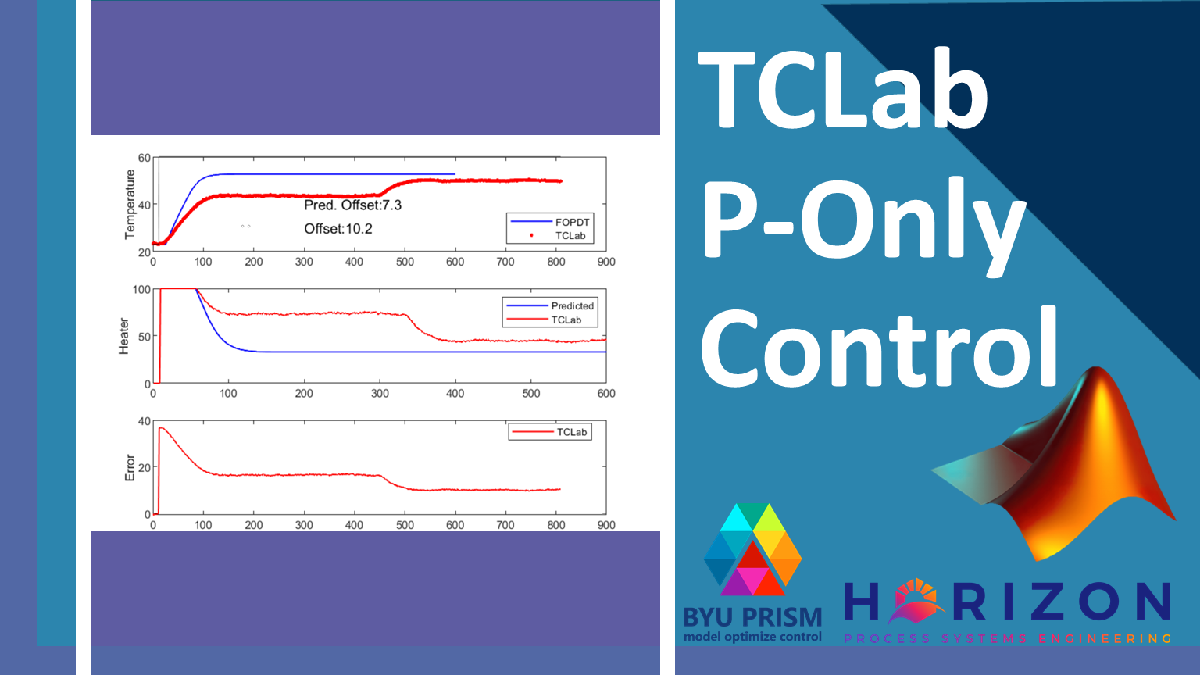

### [View Solution Video](https://youtu.be/rvT8lS-Jbvg)

Functions for Offset Simulator

function dydt = fopdt(~, y, u, Kp, taup)
    dydt = (1.0/taup) * (-(y-23.0) + Kp * u);
end

function [tm, PV, OP] = pidPlot(Kc)
    n = 600; % time points to plot
    tf = 600.0; % final time
    
    % TCLab FOPDT
    Kp = 0.9;
    taup = 175.0;
    thetap = 15.0;
    
    % Create Arrays
    tm = linspace(1, tf, n); % create time vector
    P = zeros(n, 1);         % initialize proportional term
    e = zeros(n, 1);         % initialize error
    OP = zeros(n, 1);        % initialize controller output
    PV = ones(n, 1)*23.0;    % initialize process variable
    SP = ones(n, 1)*23.0;    % initialize setpoint
    SP(10:end) = 60.0;       % step up
    
    y0 = 23.0;               % initial condition
    % loop through all time steps
    for i=2:n
        % simulate process for one time step
        ts = [tm(i-1), tm(i)];         % time interval
        [~, T] = ode45(@(t, T) fopdt(t, T, OP(max(1, round(i-1-thetap))), Kp, taup), ts, y0);
        y0 = T(end);                  % record new initial condition
        
        % calculate new OP with PID
        PV(i) = y0;                 % record PV
        e(i) = SP(i) - PV(i);       % calculate error = SP - PV
        P(i) = Kc * e(i);           % calculate proportional term
        OP(i) = P(i);               % calculate new controller output
        
        % Clip extreme values
        if OP(i)>=100
            OP(i) = 100.0;
        end
        if OP(i)<=0
            OP(i) = 0.0;
        
        end
    end
    offset = PV(end) - SP(end);
    
    figure(1)
    subplot(2,2,1)
    plot(tm, SP, 'b-', "LineWidth",1)
    hold on
    plot(tm, PV, 'r.')
    legend({'Setpoint' 'Temperature'}, "Location","best")
    ylabel('Temperature ($^\circ$C)', "Interpreter","latex")
    text(300, 45, 'Kc:'+string(Kc))
    text(300,35,'Offset:'+string(round(offset, 2)))
    
    subplot(2,2,2)
    plot(tm, P)
    ylabel('Porportional ($K_ce(t)$)', "Interpreter","latex")
    
    subplot(2,2,3)
    plot(tm, e)
    ylabel('Error $\Delta T( ^\circ$C)', "Interpreter","latex")
    xlabel('Time (s)')

    
    subplot(2,2,4)
    plot(tm, OP)
    ylabel('Heater (%)')
    xlabel('Time (s)')
end